# Simulating other feedback topologies for the R-regulator system

%% CONSTANTS
global a1 a2 b1 b2 d1 d2 k1 k2 k3 eta;
a1 = 0.1; % min^-1
a2 = 0.4; % min^-1
b1 = 2;%e-9; % M * min^-1
b2 = 1;%e-9; % M * min^-1
d1 = 1; % min^-1
d2 = 1; % min^-1
k1 = 0.5; % min^-1
k2 = 1; % min^-1
k3 = 2;%e-9; % M * min^-1
eta = 10;%e-9; % M * min^-1

## 2. 1 excitatory feedback connection

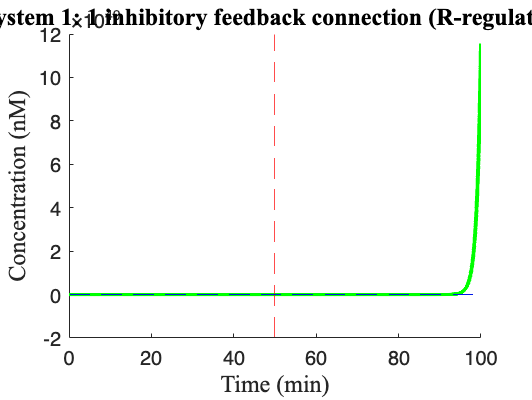

%% CL system 2: 1 excitatory fb connection
% ODE function
function dydt=sol(t,y)
    global a1 a2 b1 b2 d1 d2 k1 k2 k3 eta;
    p = 2;
    dydt(1,1)=b1 - d1*y(1) + a1*y(2) + p*heaviside(t-50);%Y1                                  
    dydt(2,1)=b2 - d2*y(2) + a2*y(1) + k3*y(4); %Y2
    dydt(3,1)=k1*y(1) - eta*y(3)*y(4); %Z1
    dydt(4,1)=k2*y(2) - eta*y(3)*y(4); %Z2
end

tspace=linspace(0,100,10000); %time
[t,y]=ode23s(@sol,tspace,[0; 0; 0; 0]); % solve ODE

% calculate SS values
lambda1 = d1*k2 - a1*k1;
lambda2 = b2*(d1*k2 - a1*k1) - b1*(d2*k1 - a2*k2);
Y1_ss = b1*k2 / lambda1;
Y2_ss = b1*k1 / lambda1;
Y_ratio_ss = k2/k1;
Z1_ss = -(b1*k1*k2*k3)/(eta*lambda2);
Z2_ss = -lambda2 / (k3*lambda1);

figure

hold on
plot(t,y(:, 1),'color','[0 1 0]', LineWidth=2);
% plot(t,y(:, 2),'color','[0 1 0]', LineWidth=2);
% plot(t,y(:, 1)./y(:, 2),'--', LineWidth=2);
% plot(t,y(:, 3),'color','[0 0 1]', LineWidth=2);
% plot(t,y(:, 4),'color','[0 0 1]', LineWidth=2);

xline(50, '--r')
yline(Y1_ss, '--g'); yline(Y2_ss, '--g');
yline(Y_ratio_ss, '--g');
yline(Z1_ss, '--b'); yline(Z2_ss, '--b');
hold off


xlabel('Time (min)','FontName', 'Times New Roman','FontSize',12) 
ylabel('Concentration (nM)','FontName', 'Times New Roman','FontSize',12) 
title('Closed loop system 1: 1 inhibitory feedback connection (R-regulator) (Figure 4A)', 'FontName', 'Times New Roman','FontSize',12)

% legend('Y1', 'Y2', 'Y1/Y2', 'dist. time', 'Y1*', 'Y2*', 'Y1*/Y2*', 'Z1*', 'Z2*')